# 案例：绘制带斜线填充的曲线图

关键点：斜线填充，暂时没有好的方法，用了比较笨的方法，用直线一条条绘制，找准坐标即可；

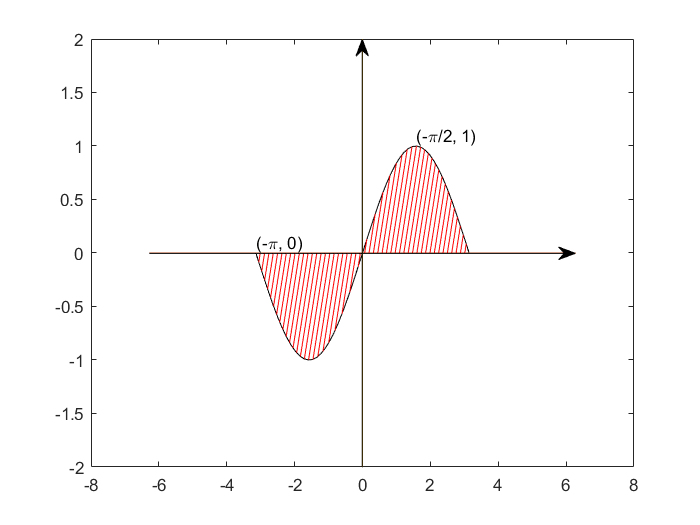

clear;clc;
syms t
n = 50;
x = linspace(-pi, pi, n);
y = sin(x);
ax = axes;
% 曲线
plot(ax, x, y, 'k');
hold on
% 画带箭头 x 轴和 y 轴
PlotLineArrow(ax, [-2*pi, 2*pi], [0, 0], 'k');
PlotLineArrow(ax, [0, 0], [-2, 2], 'k');
% 计算所有的斜线 一条斜线两个点
xx = zeros(1, n);
for i = 1:n
    % 这个方程用来计算斜线的位置
    f1 = 2*(t - x(i));
    f2 = sin(t);
    sol = vpasolve(f1 == f2, t);
    xx(i) = double(sol);
end
yy = sin(xx);
% 画斜线
for i = 1:n
    % 分 x 正负情况
    if x(i) < 0
        plot([xx(i), x(i)], [yy(i), 0], 'r');
    else
        plot([x(i), xx(i)], [0, yy(i)], 'r');
    end
end
hold off
% 几个关键点
text(-pi, 0.1, '(-\pi, 0)');
text(pi/2, 1.1, '(-\pi/2, 1)');

function PlotLineArrow(obj, x, y, lineColor)
% 绘制带箭头的曲线
%{
clear; clc;
x = 1 : 10;
y = sin(x);
plot(x, y, '.')
hold on
for i = 1 : 9
    PlotLineArrow(gca, [x(i), x(i + 1)], [y(i), y(i + 1)], 'b');
end
hold off
%}
% 绘图
plot(x, y);
% 获取 Axes 位置
posAxes = get(obj, 'Position');
posX = posAxes(1);
posY = posAxes(2);
width = posAxes(3);
height = posAxes(4);
% 获取 Axes 范围
limX = get(obj, 'Xlim');
limY = get(obj, 'Ylim');
minX = limX(1);
maxX = limX(2);
minY = limY(1);
maxY = limY(2);
% 转换坐标
xNew = posX + (x - minX) / (maxX - minX) * width;
yNew = posY + (y - minY) / (maxY - minY) * height;
% 画箭头
annotation('arrow', xNew, yNew, 'color', lineColor);
end